# Create figures 6-10

old file was figures2024rev1

prin=0;
load ExportShifts.mat
Ntable=ExportShifts;
n=sum(Ntable{:,:},"all");
I=size(Ntable,1);

## Correspondence analysis based on all the obs

CorAna(Ntable)

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1         0.27          0.07          0.50            0.50   
    dim_2         0.17          0.03          0.22            0.72   
    dim_3         0.14          0.02          0.13            0.85   
    dim_4         0.12          0.01          0.10            0.94   
    dim_5         0.07          0.01          0.04            0.98   
    dim_6         0.04          0.00          0.01            0.99   
    dim_7         0.04          0.00          0.01            1.00   

ROW POINTS
Results for dimension: 1
          Scores    CntrbPnt2In    

ans = struct with fields:
                       Lr: [17×1 string]
                       Lc: {'x16-27'  'x28-38'  'x39-40'  'x50-63'  'x72-83'  'x84-85'  'x86-89'  'x90-92'}
                        N: [17×8 double]
                   Ntable: [17×8 table]
                        I: 17.00
                        J: 8.00
                        n: 2455.00
                     Nhat: [17×8 double]
                Nhattable: [17×8 table]
                        P: [17×8 double]
                   Ptable: [17×8 table]
                        r: [17×1 double]
                       Dr: [17×17 double]
                        c: [8×1 double]
                       Dc: [8×8 double]
             ProfilesRows: [17×8 double]
             ProfilesCols: [17×8 double]
                        K: 7.00
                        k: 2.00
                Residuals: [17×8 double]
             TotalInertia: 0.14
                 Chi2stat: 345.32
                  CramerV: 0.14
         InertiaExplained: [7×4 do

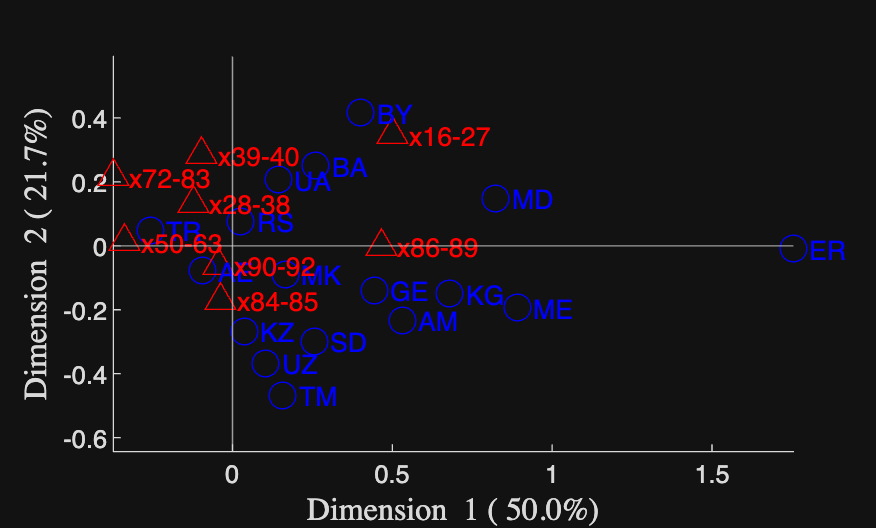

title('')

if prin==1
    % print to postscript
    print -depsc figs2024\SIca.eps;
end

## under H0

findEmp=struct;
% Generate nsimul contingency tables
findEmp.nsimul=1000; % 0;
% Under the null hypothesis of independence
findEmp.underH0=true;
% Store the nsimul robust distance sorted (for each row)
findEmp.StoreSim=true;

% Detect outlying rows using a simultaneous confidence level
conflev=1-0.01/I;
RAWH0=mcdCorAna(Ntable,'plots',0,'findEmpiricalEnvelope',findEmp, ...
    'conflev',conflev,'bdp',0.5);

Total estimated time to complete MCD:  0.41 seconds 
Finding empirical bands


## under H1

Example of findEmpiricalEnvelope a struct

findEmp=struct;
% Generate nsimul contingency tables
findEmp.nsimul=1000; % 0;
% Under the null hypothesis of independence
findEmp.underH0=false;
% Store the nsimul robust distance sorted (for each row)
findEmp.StoreSim=true;

% Detect outlying rows using a simultaneous confidence level
conflev=1-0.01/I;
RAWH1=mcdCorAna(Ntable,'plots',0,'findEmpiricalEnvelope',findEmp, ...
    'conflev',conflev,'bdp',0.5);

Total estimated time to complete MCD:  0.21 seconds 
Finding empirical bands


## Create left panel of Figure 7

plots=struct;
plots.minMD = true;
plots.inertia = false;
plots.addRowNames = true;

outFSH0=FSCorAna(RAWH0,'plots',plots,'init',round(n*0.25),'conflev',[0.05 0.95],'resc',false);

Creating empirical confidence band for minimum (weighted) Mahalanobis distance


50  500  950   50  950
Number of units which entered=3
Number of units which entered=5
Number of units which entered=5
Number of units which entered=3
Number of units which entered=4
Number of units which entered=4
Number of units which entered=3
Number of units which entered=3
Number of units which entered=7
Number of units which entered=3
Number of units which entered=4
Number of units which entered=6

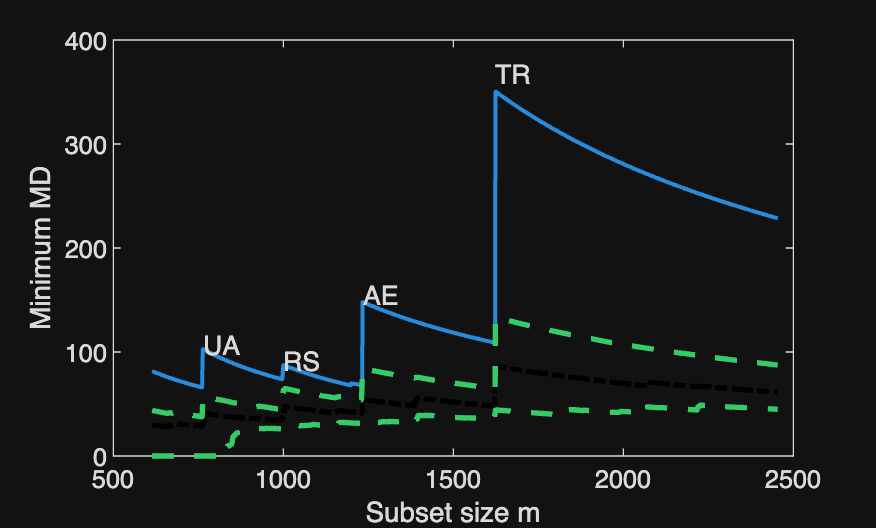

title('')
ylabel('Minimum MD')

h = findobj('Type','figure','Tag','pl_in');   % find figure handles with that tag
if ~isempty(h)
    close(h)                                  
end

if prin==1
    % print to postscript
    print -depsc figs2024\SiFSH0.eps;
end

## Create right panel of Figure 7 (Under H0 rescaled)

plots=struct;
plots.minMD = true;
plots.inertia = false;
plots.addRowNames = true;

outFSH0=FSCorAna(RAWH0,'plots',plots,'init',round(n*0.25),'conflev',[0.05 0.95],'resc',true);

Creating empirical confidence band for minimum (weighted) Mahalanobis distance


50  500  950   50  950
Number of units which entered=3
Number of units which entered=5
Number of units which entered=7
Number of units which entered=5
Number of units which entered=3
Number of units which entered=5
Number of units which entered=5
Number of units which entered=5
Number of units which entered=5
Number of units which entered=3
Number of units which entered=3
Number of units which entered=6

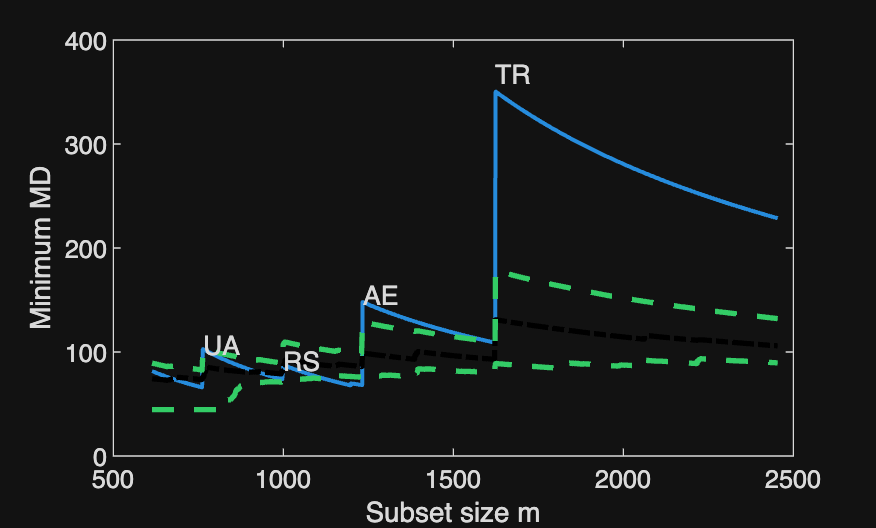

title('')
ylabel('Minimum MD')

if prin==1
    % print to postscript
    print -depsc figs2024\SiFSH0resc.eps;
end

## Create left panel of Figure 8: Under H1 not rescaled

FSCorAna(RAWH1,'plots',plots,'init',round(n*0.25),'conflev',[0.05 0.95],'resc',false);

Creating empirical confidence band for minimum (weighted) Mahalanobis distance


50  500  950   50  950
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3

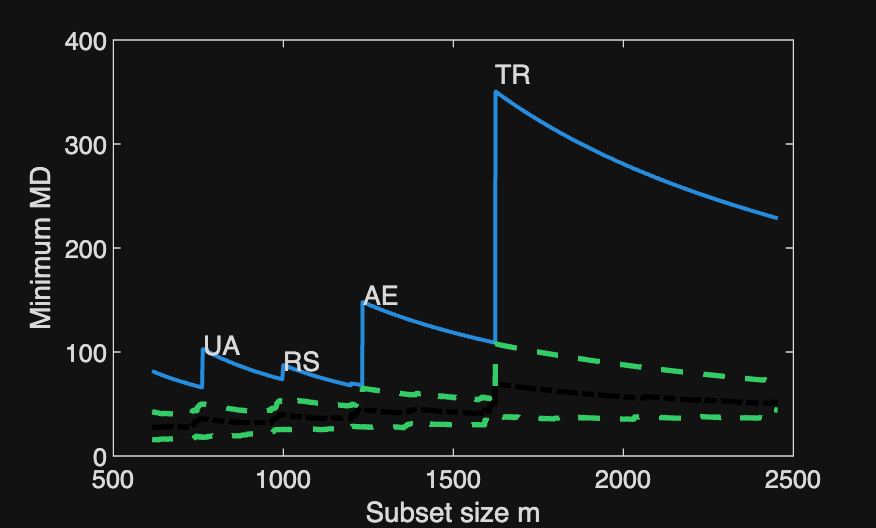

title('')
ylabel('Minimum MD')

% ylabel('')
if prin==1
    % print to postscript
    print -depsc figs2024\SiFSH1.eps;
end

## Create right panel of Figure 8: Under H1 rescaled

plots.addBonfLine=true;
outFSH1=FSCorAna(RAWH1,'plots',plots,'init',round(n*0.25),'conflev',0.90,'resc',true);

Creating empirical confidence band for minimum (weighted) Mahalanobis distance
Number of units which entered=5
Number of units which entered=6
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3
Number of units which entered=3

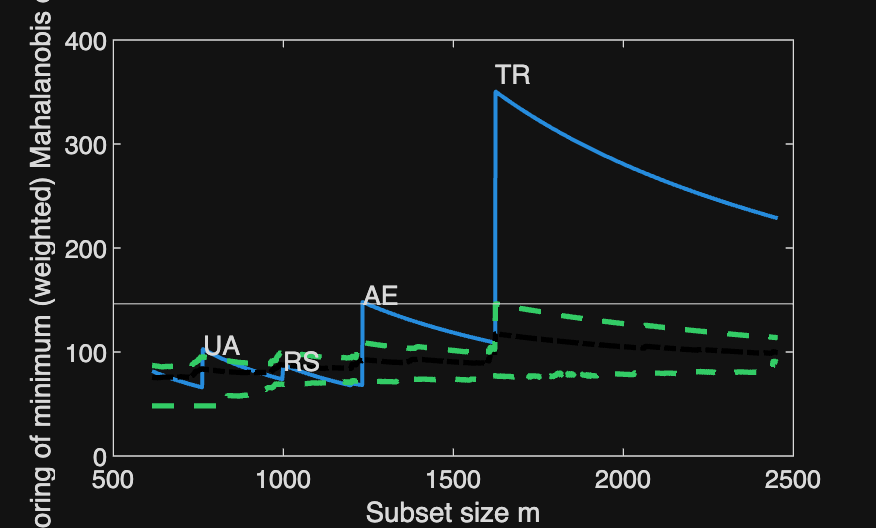

title('')

% ylabel('Minimum MD')
% ylim([40 400])
if prin==1
    % print to postscript
    print -depsc figs2024\SiFSH1resc1.eps;
end

## Figure 9: CA with two supplementary units

selsup={'TR', 'AE'};
selactive=setdiff(Ntable.Properties.RowNames,selsup);
Nsupr=Ntable(selsup,:);
Nactive=Ntable(selactive,:);
Sup=struct;
Sup.r=Nsupr;
outCorAna=CorAna(Nactive,'Sup',Sup);

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1         0.24          0.06          0.35            0.35   
    dim_2         0.23          0.05          0.30            0.65   
    dim_3         0.18          0.03          0.20            0.85   
    dim_4         0.12          0.01          0.08            0.93   
    dim_5         0.09          0.01          0.05            0.98   
    dim_6         0.05          0.00          0.02            0.99   
    dim_7         0.03          0.00          0.01            1.00   

ROW POINTS
Results for dimension: 1
          Scores    CntrbPnt2In    

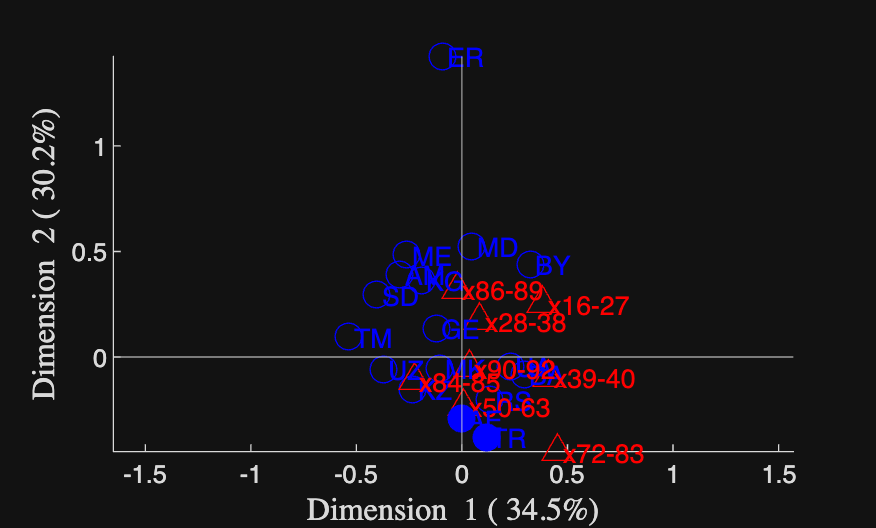

title('')


if prin==1
    % print to postscript
    print -depsc figs2024\SiCAwithSU.eps;
end

## ExportShifts

clear conflevSim=0.99; load ExportShifts.mat Ntable=ExportShifts; N=Ntable; %% Create Figure 10 conflev=0.95; % Example of findEmpiricalEnvelope a struct findEmp=struct; % Generate nsimul contingency tables findEmp.nsimul=1000; % Store the nsimul robust distance sorted (for each row) findEmp.StoreSim=true; % Under the null hypothesis of independence findEmp.underH0=true; % call to mcdCorAna RAWH0=mcdCorAna(N,'plots',0,'findEmpiricalEnvelope',findEmp,'bdp',0.5,'msg',0,'conflev',conflev); outFSH0=FSCorAna(RAWH0,'plots',0,'msg',0,'StoreSim',false,'conflev',conflevSim);

% Under the alternative hypothesis of dependence findEmp.underH0=false; % call to mcdCorAna RAWH1=mcdCorAna(N,'plots',0,'findEmpiricalEnvelope',findEmp,'bdp',0.5,'msg',0,'conflev',conflev); outFSH1=FSCorAna(RAWH1,'plots',0,'msg',0,'StoreSim',false,'conflev',conflevSim);

## Figure 10: Monitoring plots of inertia

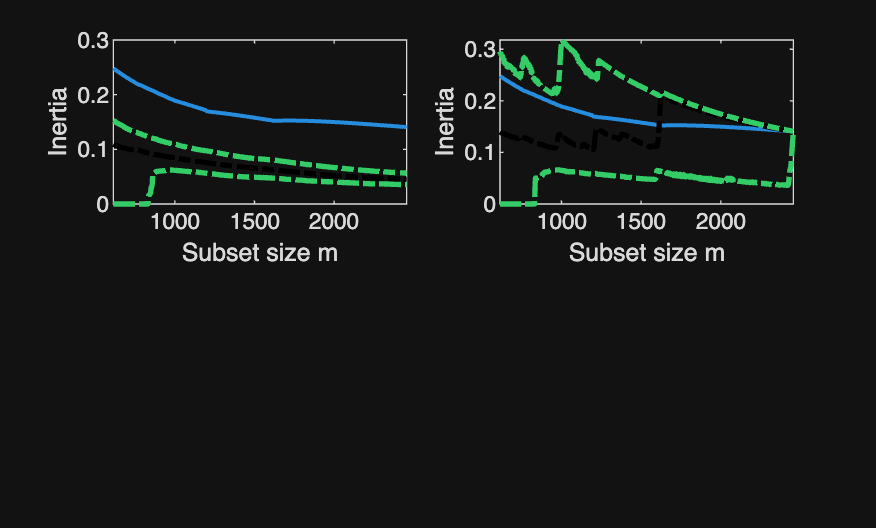

lwdreal=1.5;

figure
subplot(2,2,1)
plot(outFSH0.ine(:,1),outFSH0.ine(:,2),'LineWidth',lwdreal)


hold on
% include specified tag in the current plot
gine=outFSH0.ine(:,[1 3:end]);

lwdenv=2;
% Superimpose 50% envelope
line(gine(:,1),gine(:,3),'LineWidth',lwdenv,'LineStyle','-.','Color','k','tag','env');
% Superimpose alpha1% and alpha2% envelope
line(gine(:,1),gine(:,2),'LineWidth',lwdenv,'LineStyle','-.','Color',[0.2 0.8 0.4],'tag','env');
line(gine(:,1),gine(:,4),'LineWidth',lwdenv,'LineStyle','-.','Color',[0.2 0.8 0.4],'tag','env');
ylabel('Inertia')
xlabel('Subset size m')

subplot(2,2,2)
plot(outFSH1.ine(:,1),outFSH1.ine(:,2),'LineWidth',lwdreal)

hold on
% include specified tag in the current plot
gine=outFSH1.ine(:,[1 3:end]);

lwdenv=2;
% Superimpose 50% envelope
line(gine(:,1),gine(:,3),'LineWidth',lwdenv,'LineStyle','-.','Color','k','tag','env');
% Superimpose alpha1% and alpha2% envelope
line(gine(:,1),gine(:,2),'LineWidth',lwdenv,'LineStyle','-.','Color',[0.2 0.8 0.4],'tag','env');
line(gine(:,1),gine(:,4),'LineWidth',lwdenv,'LineStyle','-.','Color',[0.2 0.8 0.4],'tag','env');
ylabel('Inertia')
xlabel('Subset size m')

if prin==1
    print -depsc figs\I6.eps;
end